# Introduction to Drones - 22AIE448

**3D Mapping using a Monocular Camera and Control by Visual-Inertial Odometry (VIO)**

Group CD2 : Ravishanmugam K, Ishwarya Murugesan, Aparna Bharani, Cibikumar B, Akhilan S

School of Artificial Intelligence, Amrita Vishwa Vidyapeetham

**Toy model 3 - Model 2, Part 1 : learning the drone from flight data with DMDc (blocks 1 and 2)**

Run this file with the folder `toy_model3` as the current folder (it uses `DroneLib.m`). It saves `dmdc_model.mat`, which M2_2 and M2_3 load.

clearvars
clear all
ready = true;
PUBLISH = not(ready);   % make this PUBLISH = ready; to export the file as PDF

clearvars -except PUBLISH ready

## Model 2 - the flow

Model 1 needs the physics ($m$, $J$, rotor constants). Model 2 asks: **if we only had recorded flight data, could we still build a good controller?**

- Blocks 1-2 : **flight data** and **DMDc** - learn $x_{k+1} = Ax_k + Bu_k$ from data  *(this file)*

- Blocks 3-6 : **Bellman**, **LQR**, **Riccati recursion**, **DARE** - the best gain $K$  *(M2_2_LQR_Bellman_Riccati_DARE)*

- Blocks 7-10 : **MPC**, **QP**, **receding horizon**, **apply to the drone**  *(M2_3_MPC_QP_Apply_to_Drone)*

## Block 1 - Nonlinear flight data

Every $\Delta t = 0.04$ s (25 Hz = `control_rate` in `controller.yaml`) we log


$$x_k = \left[\begin{array}{c} p_k - p_{ref}\\ v_k\\ \textrm{Log}(R_k)\\ \omega_k \end{array}\right] \in R^{12}, \qquad u_k = \left[\begin{array}{c} T_k - mg\\ \tau_k \end{array}\right] \in R^{4} \qquad \rightarrow (M2.1)$$


- **Deviations from hover.** Hover is a balance point (all derivatives zero), so near hover the model has no constant term and $x_{k+1} = Ax_k + Bu_k$ can fit the data.

- **Log®** turns the 3x3 rotation into 3 numbers (near hover: roll, pitch, yaw).

- **A pilot plus random excitation.** A free drone is unstable, so a simple stabilising pilot (the role ArduPilot plays) flies it. If the input were **only** feedback, $u = -K_0x$, the data could not tell the drone apart from the pilot, so we add random pushes ($\pm$2 N, $\pm$0.03 N m, held 0.2 s).

P  = DroneLib.params();
dt = 1/25;  nSub = 8;              % 25 Hz logging, physics at 200 Hz in between
u_trim = [P.m*P.g0; 0; 0; 0];      % hover input
rng(21);
K = 625;  nRuns = 5;               % 5 flights of 25 s (4 to learn, 1 to test)
runs = cell(1, nRuns);
for r = 1:nRuns
    x = DroneLib.pack(P.p_hover + 0.3*randn(3,1), 0.1*randn(3,1), DroneLib.expSO3(0.05*randn(3,1)), zeros(3,1));
    Xr = zeros(12, K+1);  Ur = zeros(4, K);  Xw = zeros(3, K+1);  exc = zeros(4,1);
    for k = 1:K+1
        Xw(:,k) = x(1:3);
        Xr(:,k) = DroneLib.to_dev(x, P.p_hover) + [1e-3*ones(6,1); 5e-4*ones(3,1); 1e-3*ones(3,1)].*randn(12,1);
        if k == K+1, break, end
        if mod(k-1, 5) == 0, exc = [2; 0.03; 0.03; 0.01].*(2*rand(4,1) - 1); end
        [~, ~, u_app] = DroneLib.mixer(u_trim + DroneLib.pilot(Xr(:,k), P) + exc, P);
        Ur(:,k) = u_app - u_trim;
        d = [0.1*randn(3,1); 2e-4*randn(3,1)];
        for j = 1:nSub, x = DroneLib.rk4(x, u_app, dt/nSub, P, d); end
    end
    runs{r} = struct('X', Xr, 'U', Ur, 'Xw', Xw);
end
tilt_max_deg = rad2deg(max(cellfun(@(s) max(vecnorm(s.X(7:8,:))), runs)))

tilt_max_deg = 6.4611

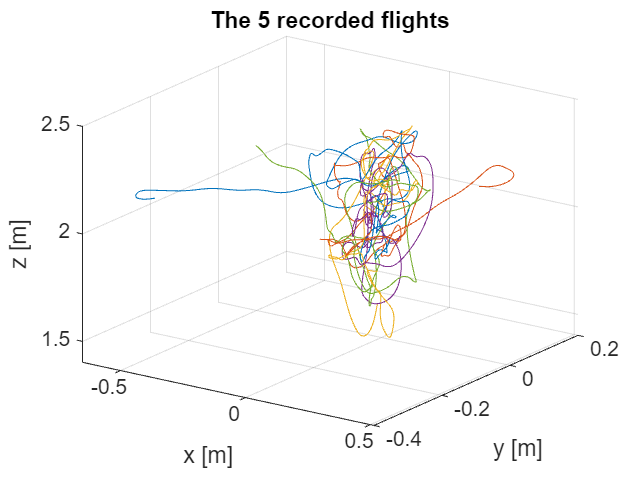

figure
hold on
for r = 1:nRuns, plot3(runs{r}.Xw(1,:), runs{r}.Xw(2,:), runs{r}.Xw(3,:)); end
hold off; grid on; view(35, 25)
xlabel("x [m]"); ylabel("y [m]"); zlabel("z [m]"); title("The 5 recorded flights")

## Block 2 - DMDc (Dynamic Mode Decomposition with control)

Put the snapshots side by side:


$$X = [x_1\ \cdots\ x_{N-1}], \qquad X^+ = [x_2\ \cdots\ x_N], \qquad U = [u_1\ \cdots\ u_{N-1}] \qquad \rightarrow (M2.2)$$


We want one matrix $G = [A\ B]$ with $X^+ \approx G\,\Omega$, where $\Omega = \left[\begin{array}{c} X\\ U \end{array}\right]$. Least squares: minimise the sum of squared prediction errors $||X^+ - G\Omega||^2$. Setting the derivative to zero, $-2(X^+ - G\Omega)\Omega^T = 0$, gives


$$G\,\Omega\Omega^T = X^+\Omega^T \quad \Rightarrow \quad [A\ \ B] = X^+\Omega^T(\Omega\Omega^T)^{-1} = X^+\left[\begin{array}{c} X\\ U \end{array}\right]^{\dagger} \qquad \rightarrow (M2.3)$$



$$x_{k+1} \approx A\,x_k + B\,u_k \qquad \rightarrow (M2.4)$$


(This is exactly the EDMD idea `K = Psi2*pinv(Psi1)` from the Lotka-Volterra notes, with the input added.)

**Toy example by hand.** True system $x_{k+1} = 0.9x_k + 0.5u_k$; three recorded steps $X = [1,\ 1.4,\ 0.76]$, $U = [1,\ -1,\ 0.5]$, $X^+ = [1.4,\ 0.76,\ 0.934]$.


$$\Omega\Omega^T = \left[\begin{array}{cc} 3.5376 & -0.02\\ -0.02 & 2.25 \end{array}\right], \quad X^+\Omega^T = [3.17384\ \ 1.107] \quad \Rightarrow \quad [a\ \ b] = [0.9\ \ 0.5]$$


X  = [1 1.4 0.76];   U = [1 -1 0.5];   Xp = [1.4 0.76 0.934];
Om = [X; U];
OmOmT = Om*Om'

OmOmT =     3.5376   -0.0200
   -0.0200    2.2500


XpOmT = Xp*Om'

XpOmT =     3.1738    1.1070


ab    = Xp*pinv(Om)          % recovers a = 0.9 and b = 0.5

ab =     0.9000    0.5000


**The drone** (flights 1-4, 2500 snapshots):

Xa = []; Xpa = []; Ua = [];
for r = 1:4
    Xa  = [Xa,  runs{r}.X(:, 1:end-1)];
    Xpa = [Xpa, runs{r}.X(:, 2:end)];
    Ua  = [Ua,  runs{r}.U];
end
Omega = [Xa; Ua];
rank_Omega = rank(Omega)                % must be 12 + 4 = 16 (enough excitation)

rank_Omega = 16

G = Xpa*pinv(Omega);
A = G(:, 1:12);
B = G(:, 13:16);

**Compare with the physics.** If we knew $m$ and $J$, the exact discrete model would be the zero-order-hold version of the Jacobians of Model 1: $\exp\left(\left[\begin{array}{cc} A_c & B_c\\ 0 & 0 \end{array}\right]\Delta t\right) = \left[\begin{array}{cc} A_{phys} & B_{phys}\\ 0 & I \end{array}\right]$

[Ac, Bc] = DroneLib.jacobians(DroneLib.pack(P.p_hover, zeros(3,1), eye(3), zeros(3,1)), u_trim, P);
E = expm([Ac Bc; zeros(4,16)]*dt);
A_phys = E(1:12, 1:12);   B_phys = E(1:12, 13:16);
entry   = ["A(1,4) = dt"; "A(4,8) = g dt"; "A(5,7) = -g dt"; "B(6,1) = dt/m"; "B(10,2) = dt/Jx"; "B(12,4) = dt/Jz"];
learned = [A(1,4); A(4,8); A(5,7); B(6,1); B(10,2); B(12,4)];
physics = [A_phys(1,4); A_phys(4,8); A_phys(5,7); B_phys(6,1); B_phys(10,2); B_phys(12,4)];
table(entry, learned, physics)

ans = 6×3 table
          entry          learned     physics 
    _________________    ________    ________

    "A(1,4) = dt"        0.039886        0.04
    "A(4,8) = g dt"       0.39085      0.3924
    "A(5,7) = -g dt"     -0.38621     -0.3924
    "B(6,1) = dt/m"      0.026773    0.026667
    "B(10,2) = dt/Jx"      2.0007           2
    "B(12,4) = dt/Jz"      1.0096           1


error_A_pct = 100*norm(A - A_phys)/norm(A_phys)

error_A_pct = 2.6061

error_B_pct = 100*norm(B - B_phys)/norm(B_phys)

error_B_pct = 1.1166

learned_mass = dt/B(6,1)                  % the data "knows" the mass

learned_mass = 1.4940

**Test on flight 5** (never used for learning): predict 1 s (25 steps) ahead with only the inputs.

Xv = runs{5}.X;  Uv = runs{5}.U;  H = 25;
err_dmd = [];  err_phys = [];
for k0 = 1:5:size(Uv,2) - H
    xd = Xv(:,k0);  xp = Xv(:,k0);
    for j = 0:H-1
        xd = A*xd + B*Uv(:,k0+j);
        xp = A_phys*xp + B_phys*Uv(:,k0+j);
    end
    err_dmd(end+1)  = norm(xd(1:3) - Xv(1:3, k0+H));
    err_phys(end+1) = norm(xp(1:3) - Xv(1:3, k0+H));
end
one_second_error_cm_DMDc    = 100*mean(err_dmd)

one_second_error_cm_DMDc = 1.3291

one_second_error_cm_physics = 100*mean(err_phys)

one_second_error_cm_physics = 1.2595

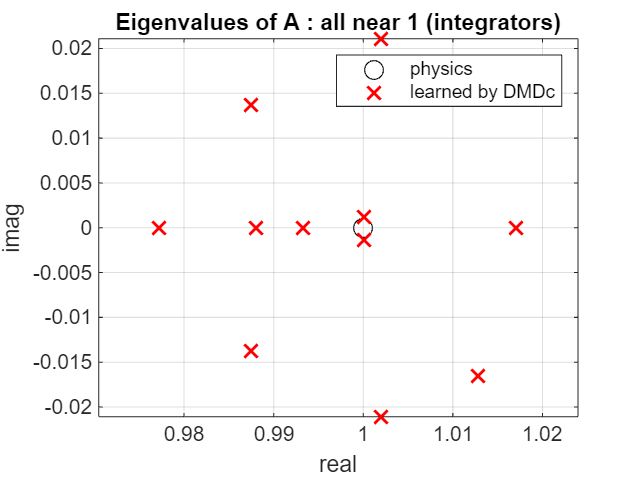

figure
plot(real(eig(A_phys)), imag(eig(A_phys)), 'ko', MarkerSize=9); hold on
plot(real(eig(A)), imag(eig(A)), 'rx', MarkerSize=9, LineWidth=1.5); hold off
grid on; axis equal; xlabel("real"); ylabel("imag")
legend("physics", "learned by DMDc"); title("Eigenvalues of A : all near 1 (integrators)")

**In the real drone:** block 1 is a `ros2 bag record` of `/ap/v1/pose/filtered`, `/ap/v1/twist/filtered` and our commands; DMDc is run on that log. Changing the camera, battery or frame only needs a new two-minute flight.

save('dmdc_model.mat', 'A', 'B', 'A_phys', 'B_phys', 'P', 'dt', 'nSub', 'u_trim');

if(PUBLISH == ready)
    mlxfile = matlab.desktop.editor.getActive().Filename;
    [folder, name, ext] = fileparts(mlxfile);
    outfilepdf = fullfile(folder, 'pdf', [name, ext, '.pdf']);
    export(mlxfile, outfilepdf);
    if ispc
        winopen(outfilepdf);
    elseif ismac
        system(['open ' char(outfilepdf)]);
    else
        system("env -u LD_LIBRARY_PATH xdg-open '" + outfilepdf + "' &");
    end
end